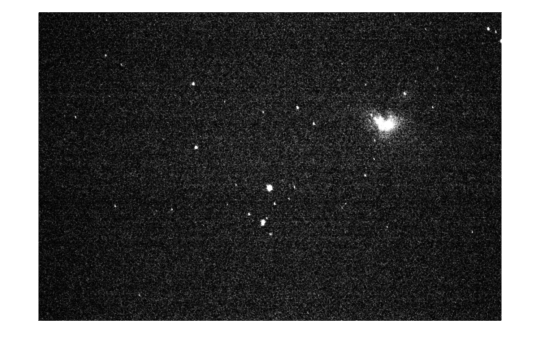

% Load the grayscale image
img = imread('orion_image.tif');
gray_img = medfilt2(im2gray(img),[3 3]);
imshow(gray_img);

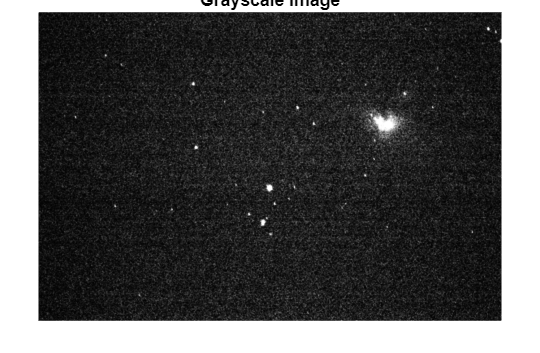


% Convert to double for colormap application (if needed)
gray_img = mat2gray(gray_img); % Normalizes image to [0, 1] range

% Apply the colormap (e.g., 'jet')
colormap_used = jet(256); % Choose the colormap and set 256 colors
colored_img = ind2rgb(gray2ind(gray_img, 256), colormap_used);

% Display the grayscale and RGB images
figure, imshow(gray_img), title('Grayscale Image');

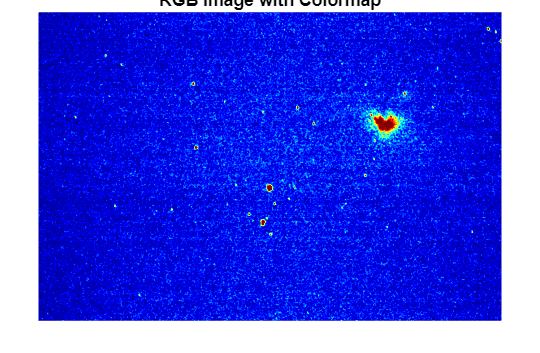

figure, imshow(colored_img), title('RGB Image with Colormap');

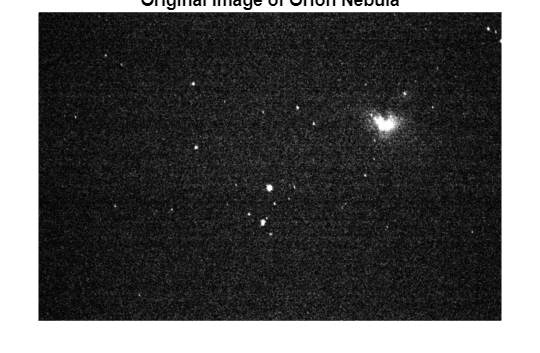

img = gray_img;
% Convert to grayscale if it's a color image
if size(img, 3) == 3
    gray_img = rgb2gray(img);
else
    gray_img = img; % Already grayscale
end

% Normalize the grayscale image
gray_img = mat2gray(gray_img);

% Create a custom colormap resembling the Orion Nebula colors
orion_colormap = [
    0 0 0;         % Black for space background
    0.1 0 0.2;     % Deep purple
    0 0 0.5;       % Dark blue
    0 0.3 0.6;     % Teal blue
    0.2 0.7 0.7;   % Cyan
    1 1 1          % White highlights
];

% Convert to indexed image
indexed_img = gray2ind(gray_img, size(orion_colormap, 1));

% Apply the colormap
colored_img = ind2rgb(indexed_img, orion_colormap);

% Display the original and color-mapped images
figure, imshow(img), title('Original Image of Orion Nebula');

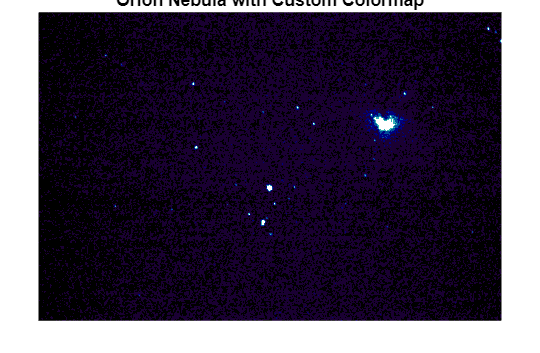

figure, imshow(colored_img), title('Orion Nebula with Custom Colormap');


imwrite(colored_img, 'orion_blue_image.tif');

img = gray_img;
% Convert to grayscale if it's a color image
if size(img, 3) == 3
    gray_img = rgb2gray(img);
else
    gray_img = img; % Already grayscale
end

% Normalize the grayscale image
gray_img = mat2gray(gray_img);

orion_colormap = [
    0 0 0;           % Black for space background
    0 0.1 0;         % Very dark green
    0 0.3 0.1;       % Dark green with a hint of blue
    0 0.5 0.2;       % Medium dark green
    0 0.7 0.4;       % Light green
    0.5 1 0.5;       % Bright green
    1 1 1            % White highlights
];

% Convert to indexed image
indexed_img = gray2ind(gray_img, size(orion_colormap, 1));

% Apply the colormap
colored_img = ind2rgb(indexed_img, orion_colormap);

% Display the original and color-mapped images
figure, imshow(img), title('Original Image of Orion Nebula');

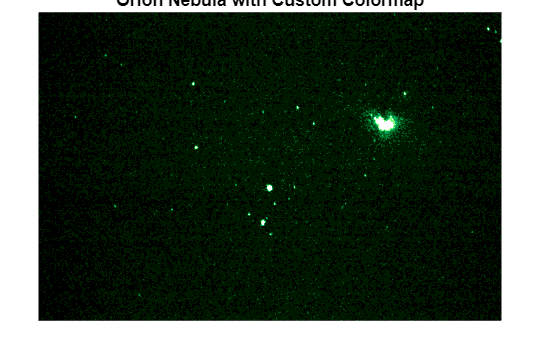

figure, imshow(colored_img), title('Orion Nebula with Custom Colormap');


imwrite(colored_img, 'orion_green_image.tif');

img = gray_img;
% Convert to grayscale if it's a color image
if size(img, 3) == 3
    gray_img = rgb2gray(img);
else
    gray_img = img; % Already grayscale
end

% Normalize the grayscale image
gray_img = mat2gray(gray_img);

orion_colormap = [
    0 0 0;           % Black for space background
    0.2 0 0;         % Deep dark red
    0.5 0 0.2;       % Dark red with a hint of pink
    0.7 0.1 0.4;     % Medium red-pink
    0.9 0.4 0.6;     % Lighter pink
    1 0.7 0.8;       % Soft pink
    1 1 1            % White highlights
];


% Convert to indexed image
indexed_img = gray2ind(gray_img, size(orion_colormap, 1));

% Apply the colormap
colored_img = ind2rgb(indexed_img, orion_colormap);

% Display the original and color-mapped images
figure, imshow(img), title('Original Image of Orion Nebula');

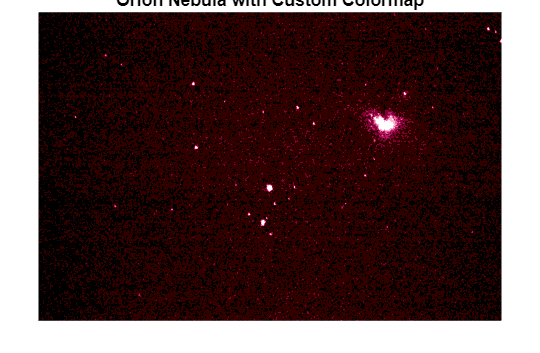

figure, imshow(colored_img), title('Orion Nebula with Custom Colormap');


imwrite(colored_img, 'orion_red_image.tif');

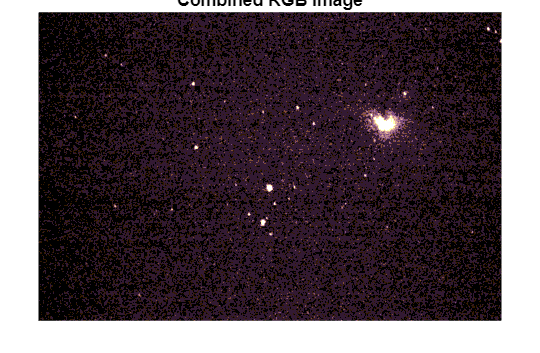

% Load the RGB images
redChannel = imread('orion_red_image.tif');       % Red channel
greenChannel = imread('orion_green_image.tif');   % Green channel
blueChannel = imread('orion_blue_image.tif');     % Blue channel

% Ensure the channels are in the correct format and have the same dimensions
% If these images are already RGB, you can extract the corresponding channels:
% For demonstration, let's assume these images are 3D arrays
if size(redChannel, 3) ~= 3 || size(greenChannel, 3) ~= 3 || size(blueChannel, 3) ~= 3
    error('All images must be RGB images of size MxNx3.');
end

% Combine the individual RGB channels into a single RGB image
rgbImage = cat(3, redChannel(:,:,1), greenChannel(:,:,2), blueChannel(:,:,3));

% Display the final RGB image
imshow(rgbImage);
title('Combined RGB Image');


imwrite(rgbImage, 'orion_rgb_image.tif');

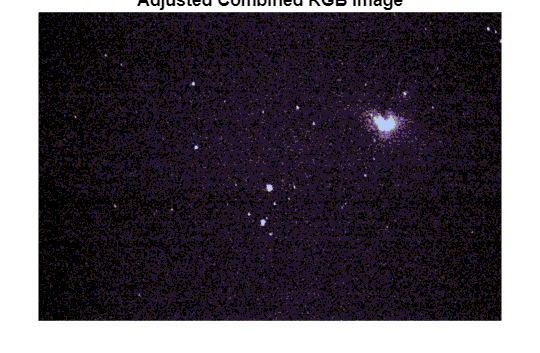

% Load the RGB images (assuming each is a 3D image with the RGB information in each channel)
redChannel = imread('orion_red_image.tif');       % Red channel
greenChannel = imread('orion_green_image.tif');   % Green channel
blueChannel = imread('orion_blue_image.tif');     % Blue channel

% Define scaling factors for each channel to adjust the proportions
% You may need to adjust these values experimentally
redScale = 0.7;   % Increase the intensity of red
greenScale = 0.8; % Decrease the intensity of green
blueScale = 1.0;  % Keep blue as it is, or adjust as needed

% Extract the RGB components and apply the scaling
redChannel = redScale * double(redChannel(:,:,1));  % Convert to double for scaling
greenChannel = greenScale * double(greenChannel(:,:,2));
blueChannel = blueScale * double(blueChannel(:,:,3));

% Clip values to the valid range [0, 255]
redChannel = uint8(min(max(redChannel, 0), 255));
greenChannel = uint8(min(max(greenChannel, 0), 255));
blueChannel = uint8(min(max(blueChannel, 0), 255));

% Combine the adjusted RGB channels into a single RGB image
rgbImage = cat(3, redChannel, greenChannel, blueChannel);

% Display the final RGB image
imshow(rgbImage);
title('Adjusted Combined RGB Image');


% Save the final RGB image
imwrite(rgbImage, 'orion_rgb_image_adjusted.tif');


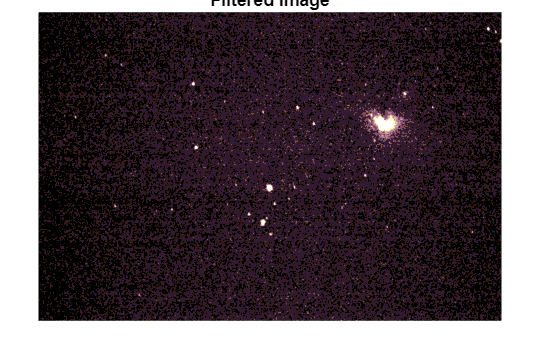

% Read the RGB image
image = rgbImage;

% Define the averaging filter (e.g., a 3x3 filter)
kernel = fspecial('average', [3, 3]);

% Apply the filter to each channel separately
filteredR = imfilter(image(:,:,1), kernel);
filteredG = imfilter(image(:,:,2), kernel);
filteredB = imfilter(image(:,:,3), kernel);

% Combine the channels back into an RGB image
filteredImage = cat(3, filteredR, filteredG, filteredB);
imshow(filteredImage);
title('Filtered Image');